# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['G:\Luke\TimeEst_EEG_New'];    
Deci.SubjectList = 'gui';  
Deci.Step               = 5;
Deci.Proceed            = false;  
Deci.PCom               = false;                           % Activates Parallel Computing (if availible)
Deci.Folder.Version     = ['G:\Luke\TimeEstEEG'];    
Deci.Retroactive = true; 

## 1. Trial Definitions

Deci.DT.Starts     = {10};         %Cell Array of Markers for ETs Start.
Deci.DT.Ends       = {11};         %Cell Array of Markers for ETs End.
Deci.DT.Markers    = {[28 29 30]};


Deci.DT.Locks      = [12 17 27];
Deci.DT.Toi        = [-2 3];  

## 2. PreProcessing Steps

Deci.PP.filter.bpfreq = [.5 80];
Deci.PP.filter.bpfilter = 'yes';
Deci.PP.filter.detrend = 'yes';

Deci.ICA.do = true;
Deci.ICA.bpfreq = [1 30];
Deci.ICA.Automatic = false;

## 3. Artifact Rejection

Deci.Art.do = true;
Deci.Art.crittoilim = [-.5 1.5];
Deci.Art.RT.minlength = 200;
Deci.Art.RT.locks = [2 1];

Deci.Art.AddComponents =  false;

## 4. Analysis

Deci.Analysis.Laplace       =false;                                                               % Uses Captrak .bvct file with same name in RawData Folder
Deci.Analysis.DownSample    = 500;

%CDA
  
Deci.Analysis.Channels = {'Reinhart-All'};
Deci.Analysis.Locks         = [1];                                                          % Which Lock to Analyze
Deci.Analysis.LocksTitle    = {'Fdb Onset'};                      % Folder Title to save each Lock as
Deci.Analysis.Conditions    = {[28] [29 30]};

Deci.Analysis.CondTitle     = {'Correct' 'Incorrect'};
Deci.Analysis.Version = ['G:\Luke\Simon\ProcessedData_Correct_BBCorr'];
Deci.Analysis.ERP.do  = false;
Deci.Analysis.Freq.do  = true;

Deci_Wavelet;

Deci.Analysis.Freq.foi           = exp(linspace(log(3),log(60),40));                           % Frequency of Interest
Deci.Analysis.Freq.width         = exp(linspace(log(3),log(13),40));                                                         % Width
Deci.Analysis.Freq.Toi           = [-.5 1.5];

## 5. Plotting

Deci is running retroactive subjects


Running Deci for 25 subjects
 
----------------------
 
Plotting TotalPower
Loading Plottor for Subject #1: Simon_EEGTest1_001PS
Loading Plottor for Subject #2: Simon_EEGTest1_002PS
Loading Plottor for Subject #3: Simon_EEGTest1_007PS
Loading Plottor for Subject #4: Simon_EEGTest1_008CG
Loading Plottor for Subject #5: Simon_EEGTest1_011PS
Loading Plottor for Subject #6: Simon_EEGTest1_015CG
Loading Plottor for Subject #7: Simon_EEGTest1_018PS
Loading Plottor for Subject #8: Simon_EEGTest1_026CG
Loading Plottor for Subject #9: Simon_EEGTest1_032CG
Loading Plottor for Subject #10: Simon_EEGTest1_046PS
Loading Plottor for Subject #11: Simon_EEGTest_002CG
Loading Plottor for Subject #12: Simon_EEGTest_004PS
Loading Plottor for Subject #13: Simon_EEGTest_007CG
Loading Plottor for Subject #14: Simon_EEGTest_009PS
Loading Plottor for Subject #15: Simon_EEGTest_010CG
Loading Plottor for Subject #16: Simon_EEGTest_011CG
Loading Plottor for Subject #17: Simon_EEGTest_013PS
Loading Plottor for Su

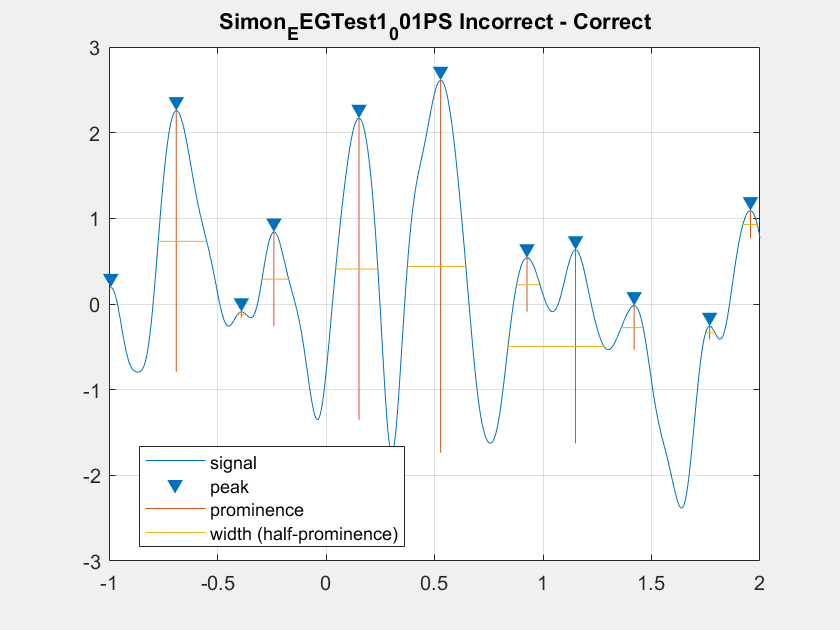

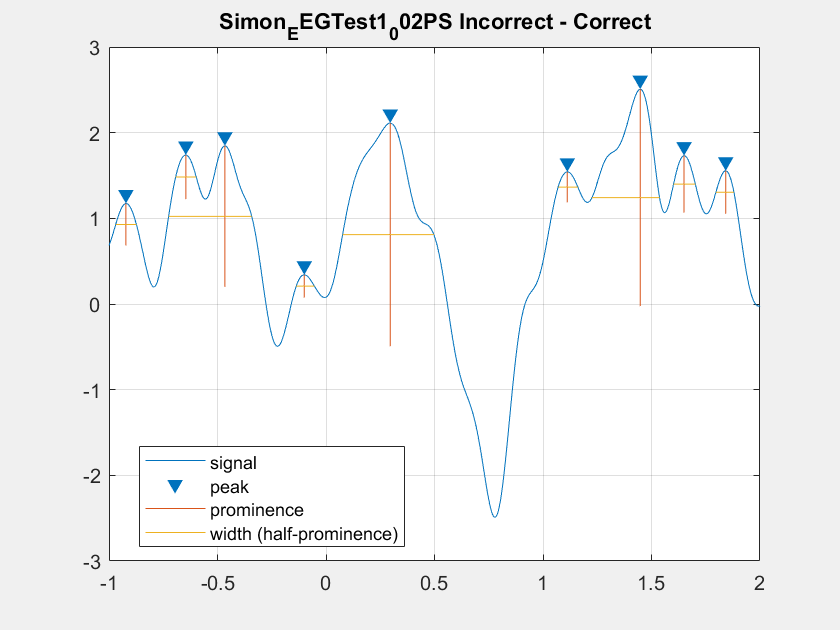

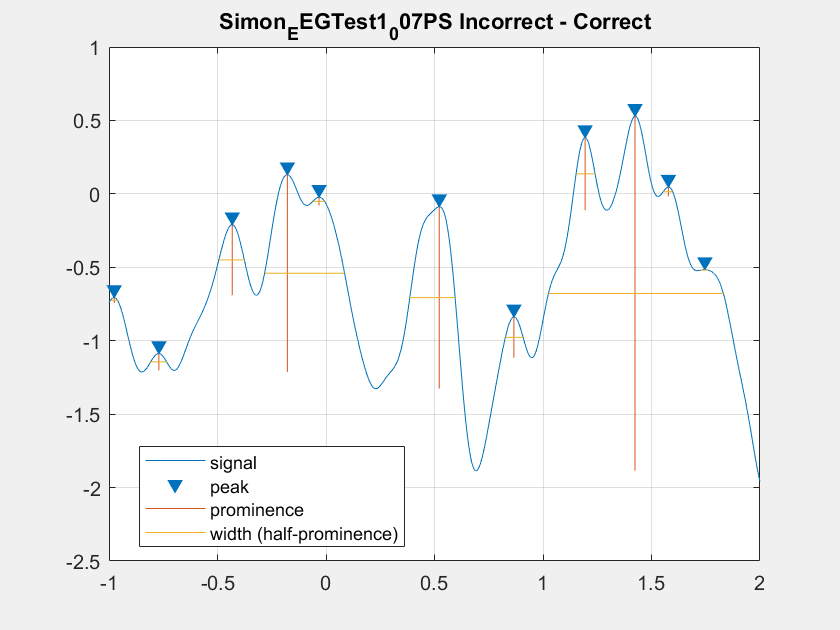

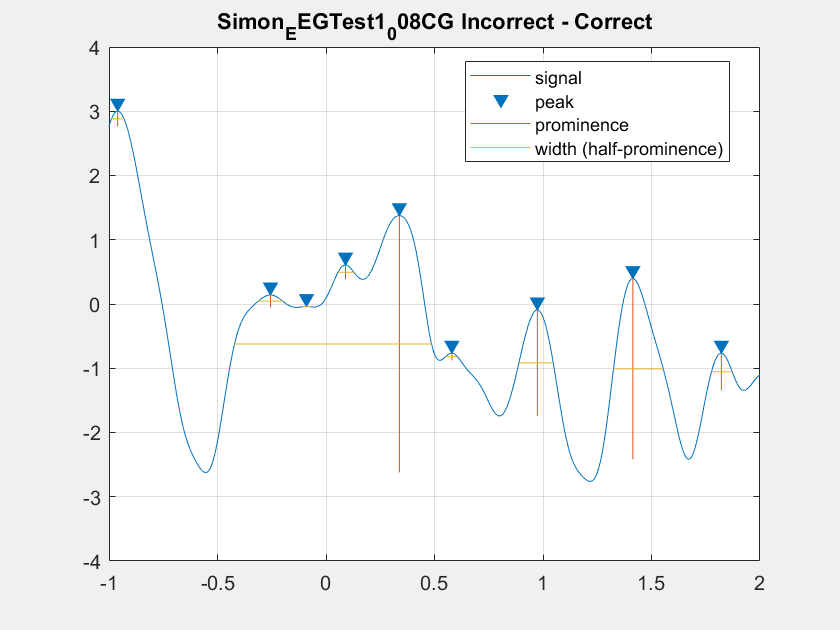

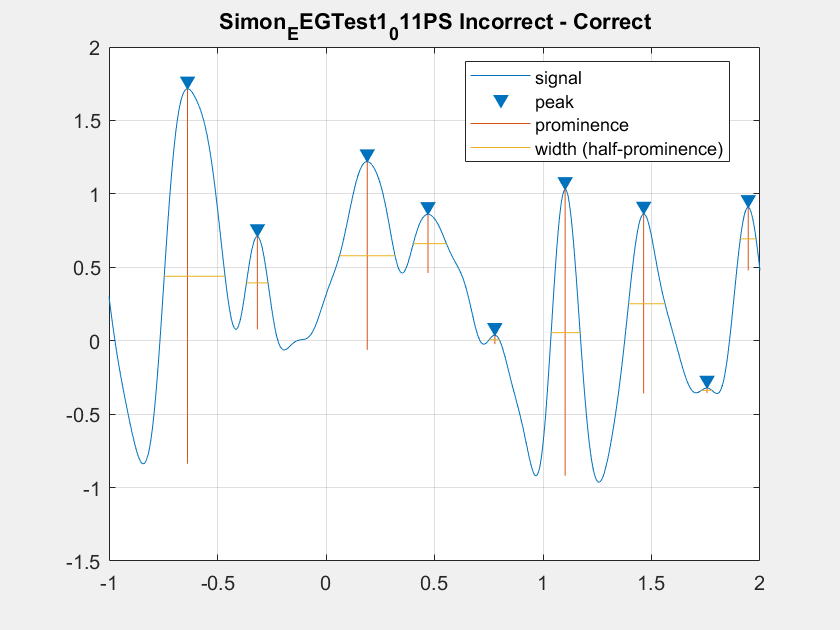

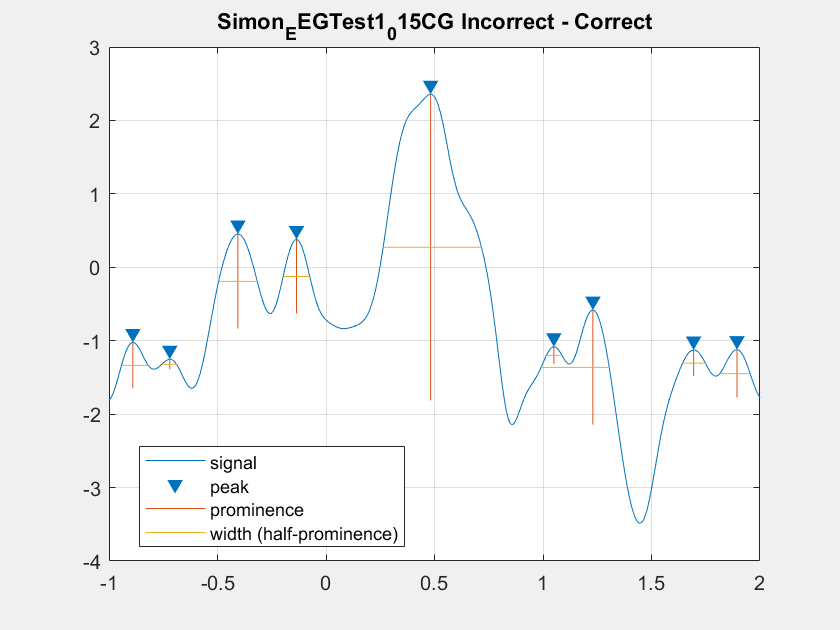

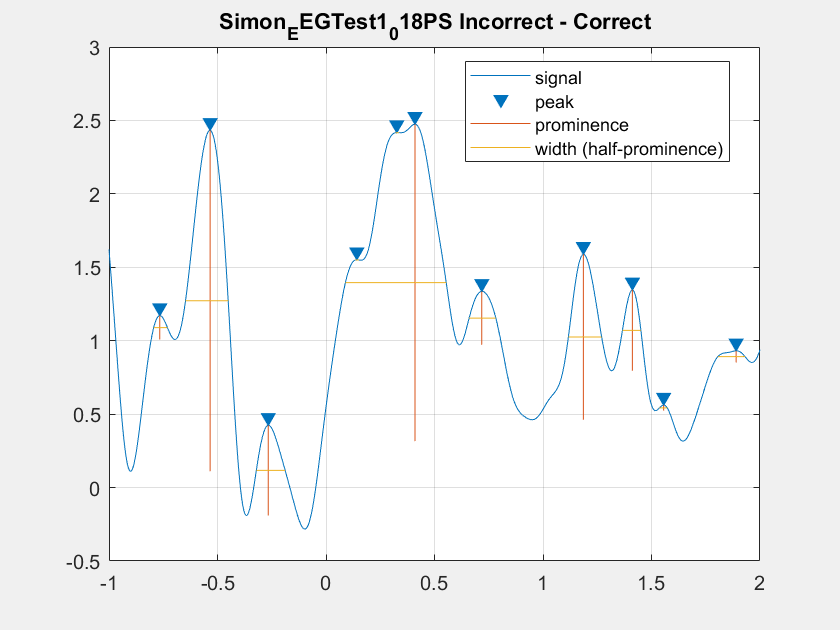

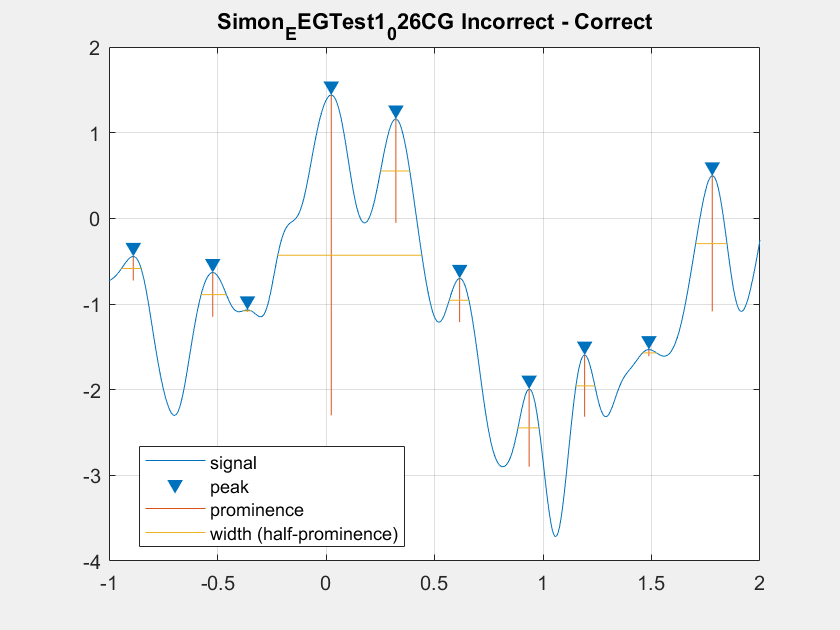

Deci.Plot.Version = [Deci.Analysis.Version];
Deci.Plot.Figures      = [false false true];
Deci.Plot.Math         = {'x2 - x1'};           % Condition Math done after Bsl, Condition Indexes are appended on.
Deci.Plot.Draw         = {[1] [2] [3]};                   % Cell array of Condition Index for each figure

Deci.Plot.Title        = {'Correct' 'Incorrect' 'Difference'};          % Title for each figure
Deci.Plot.Subtitle     = {{'Correct'} {'Incorrect'} {'Incorrect - Correct'}};     % Cell array of strings of subtitles for each Condition

Deci.Plot.BslRef = 'Stim Onset';
Deci.Plot.Lock =   'Stim Onset';
Deci.Plot.Bsl     = [-.2 0];

Deci.Run.Freq =false;
Deci.Run.ERP =false;
Deci.Run.Extra = true;

Deci.Plot.Extra.findpeaks.visualize = true;
Deci.Plot.Extra.findpeaks.toi = [0 .5];
Deci.Plot.Extra.findpeaks.trough = 1;

Deci.Plot.Extra.List = [true];
Deci.Plot.Extra.Functions = {'Deci_findpeaks' };
Deci.Plot.Extra.Params = {{Deci.Plot.Extra.findpeaks}};

Deci.Plot.GrandAverage = true;

    Deci.Plot.Topo.do    =false;
    Deci.Plot.Topo.Foi     = [4 7.5];                   % Frequency of Interest
    Deci.Plot.Topo.Toi     = [.1 .3];                   % Time of Interest
    Deci.Plot.Topo.Channel = ['Reinhart-All'];                   % Channel of Interest
       
    Deci.Plot.MTopo.do    =false;
    Deci.Plot.MTopo.Foi     = [13 20];                   % Frequency of Interest
    Deci.Plot.MTopo.Toi     = [1.3 3];                   % Time of Interest
    Deci.Plot.MTopo.ToiSegs = 5;
    Deci.Plot.MTopo.Channel = ['Reinhart-All'];      
    
    Deci.Plot.Square.do  =false;
    Deci.Plot.Square.Foi     = [1 inf];                 % Frequency of Interest
    Deci.Plot.Square.Toi     = [];                   % Time of Interest
    Deci.Plot.Square.Channel = [{'FCz'}];                % Channel of Interest
    
    Deci.Plot.Wire.do    =true;
    Deci.Plot.Wire.Foi     =   [9 13];          % Frequency of Interest
    Deci.Plot.Wire.Toi     = [];                   % Time of Interest
    Deci.Plot.Wire.Channel = {'FCz'};              % Channel of Interest
    
    Deci.Plot.Bar.do    =false;
    Deci.Plot.Bar.Foi     = [5 7.5];                 % Frequency of Interest
    Deci.Plot.Bar.Toi     = [.11 .13];                   % Time of Interest
    Deci.Plot.Bar.Channel =  {'FCz'};            % Channel of Interest
    
    Deci.Plot.Freq.Type    = 'TotalPower';
    
    if  strcmpi(Deci.Plot.BslRef, 'Rsp Onset')
        Deci.Plot.Bsl     = [-.15 -.05];
    else
        Deci.Plot.Bsl     = [-.25 -.05];
    end
    
    Deci.Plot.BslType = 'db';
    
    if Deci.Run.Extra
        Deci.Plot.BslType = 'db';
        Deci.Plot.Roi = 'maxabs';
        Deci.Plot.Stat.do = true;
        Deci.Plot.ColorMap = (CoolMap);
        
        Deci.Plot.Stat.do = true;
        Deci.Plot.Stat.Type = 'Anova/T-test';
        Deci.Plot.Stat.alpha = .05;
        Deci.Plot.Stat.correctm = 'fdr';
        
    elseif Deci.Plot.Square.do
        Omnibus = false;
        
        
        if Omnibus == true
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Comp = 'Bsl';
            Deci.Plot.Stat.alpha = .01;
            Deci.Plot.Stat.correctm = 'fdr';
            Deci.Plot.BslType = 'relchange';
            Deci.Plot.Stat.FPlots =  false;
        else
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Anova/T-test';
            Deci.Plot.Stat.alpha = .1;
            Deci.Plot.Stat.correctm = 'fdr';
        end
        Deci.Plot.Stat.FPlots =  false;
        
    elseif Deci.Plot.Topo.do 

        Perma = true;
        
        if Perma == true
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Randomize Permutation';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.FPlots =  false;
        end
    elseif Deci.Plot.Wire.do
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Anova/T-test';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.FPlots =  false;
    elseif Deci.Plot.Bar.do
        Deci.Plot.Stat.do = false;
    end
    
     Deci.Plot.Stat.twoway.do = false;
    
    Deci_Backend(Deci);